# **ELEC 4700 Assignment 3**

# **Monte-Carlo/Finite Difference Method**

**Jay Maini 101037537**

**March 18th, 2021**

# Part 1 

We can calculate the Electric field induced on the electrons by dividing the voltage applied by the length of the semiconductor. We can apply this since we assume a uniform and constant field. The force on each electron can then be calculated by multipling the Field by the elementary charge q0 = 1.60e-19. Lastly, acceleration of the particle can be found by dividing the force by the particle mass, which is m = 0.26*m0, m0 being the rest mass of the particle at 9.11e-31 kg.Thus with a semiconductor length of 200nm and SI units:

clear all
clearvars
clearvars -GLOBAL
clc
close all
format shorte

set(0, 'DefaultFigureWindowStyle', 'docked')
global C

%Physics Constants
C.q_0 = 1.60217653e-19;             % electron charge
C.hb = 1.054571596e-34;             % Dirac constant
C.h = C.hb * 2 * pi;                    % Planck constant
C.m_0 = 9.10938215e-31;             % electron mass
C.kb = 1.3806504e-23;               % Boltzmann constant
C.eps_0 = 8.854187817e-12;          % vacuum permittivity
C.mu_0 = 1.2566370614e-6;           % vacuum permeability
C.c = 299792458;                    % speed of light
C.g = 9.80665; %metres (32.1740 ft) per s²
C.am = 1.66053892e-27;


%Time interval and simulation time 
dt = 0.01e-12;
nt = 100;
%Number of particles - can be run with multiple
np = 2000;
maxXBound = 200e-9;
maxYBound = 100e-9;
x = rand(np,1)*maxXBound;
y = rand(np,1)*maxYBound;

T = 300;
m = 0.26*C.m_0;
v_th = sqrt(2*C.kb*T/m);

%New stuff for assignment #3

%Hand calculations
Voltage = 0.1;
EField = Voltage/maxXBound

EField =    5.0000e+05


E_force = EField * C.q_0

E_force =    8.0109e-14


E_accel = E_force / m

E_accel =    3.3823e+17


For the following plots, a voltage of 0.5 volts is used to better illustrate the acceleration due to the field.

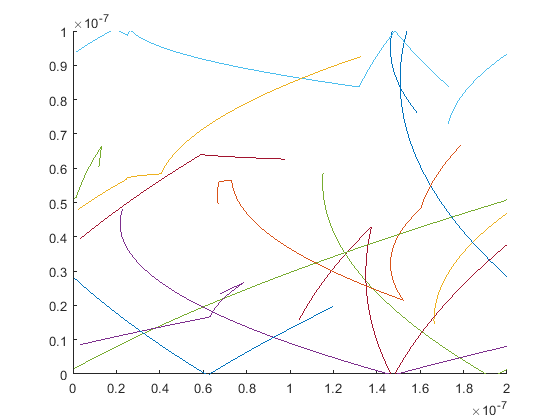

Voltage = 0.5;
EField = Voltage/maxXBound;
E_force = EField * C.q_0;
E_accel = E_force / m;


%Gives -1 or 1
%2*randi([0 1], np, 1)-1

vx = randn(np, 1)*v_th/sqrt(2);
vy = randn(np, 1)*v_th/sqrt(2);
%vy = (2*randi([0 1], np, 1)-1)*v_th/sqrt(2);
%Other Variables
t = 0;

mtc = 0.4e-12; %Mean time between collisions
%Calculate scattering probability
P_scat = 1 - exp(-dt/mtc);
%Time before scattering
T_scat = zeros(1,np);
Scatter_Time_Array = 0;
    

%Visualize a certain number of the electroncs
visuals = 7;
watcher = randi(np,visuals);
 
for i=2:nt
    %Advance the electron in time updating its position and velocity
    t(i) = t(i-1)+dt;
    %Increment Time before scattering
    T_scat = T_scat + dt;
    
    x(:,i) = x(:,i-1) + vx(:,1)*dt;
    y(:,i) = y(:,i-1) + vy(:,1)*dt;
    
    vx(:,1) = vx(:,1) + (1/2)*E_accel*dt;
    
    Jx(i) = C.q_0 * (1e15) * (1e14) * mean(vx(:,1));
    
    hold on;
    for j=1:visuals
        %Create line segments to plot
        
        plot([x(watcher(j),i-1) x(watcher(j),i)],[y(watcher(j),i-1) y(watcher(j),i)])
        hold on
    end
    xlim([0 maxXBound])
    ylim([0 maxYBound])
   
    %Plot Temperature over simulation time
    magVel = sqrt(vx.^2+vy.^2);
    avgV(i,:) = mean(magVel.^2);
    %Calculate Temperature based off average velocity
    t_thermal = (m*(avgV))./(2*C.kb);
    
    %Scattering --------------------------------------------------
    scatter = P_scat > rand(np,1);
    
    vx(scatter) = randn(length(vx(scatter)), 1)*v_th/sqrt(2);
    vy(scatter) = randn(length(vy(scatter)), 1)*v_th/sqrt(2);
    
    %Now affect the Time before scattering:
    Scatter_Time_Array = [Scatter_Time_Array T_scat(scatter)];
    T_scat(scatter) = 0;
    avgScatter = mean(Scatter_Time_Array);
    avgMFP = avgScatter*v_th;
   
  %Reflections for y axis and transmissions for the x asis
  vy((y(:,i)>maxYBound)) = -vy((y(:,i)>maxYBound));
  vy((y(:,i)<0)) = -vy((y(:,i)<0));
  %Perform vertical shift here
 
  x(x>maxXBound) = x(x>maxXBound)-maxXBound;
  x(x<0) = x(x<0)+maxXBound;
 
    
  %pause(0.01);
  
end

The relationship between the drift current density and the average carrier velocity can be modelled using the electrical current density:


$$J=\mathrm{qe}*n*v$$


Where qe is the elemenatary charge on the electrons, n is the electron density, and v is the average velocity of the electrons. Assuming n = 10e15 cm^-2, the current can be modelled over time with the average velocity being the time varying variable.

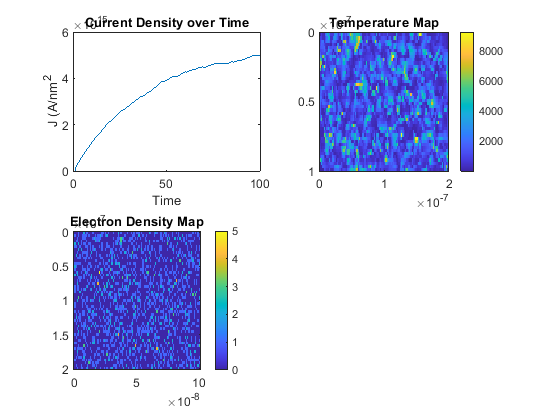

figure

subplot(2,2,1)
plot(Jx)
title('Current Density over Time')
xlabel('Time')
ylabel('J (A/nm^2')

%Temperature map

%Temperature Calculation
magVel = sqrt(vx.^2+vy.^2);
temperatures = (m*(magVel.^2))./(2*C.kb);
subplot(2,2,2)
%Create Matrix for mapping temperatures to positions
xv = linspace(min(x(:,i)), max(x(:,i)), 100);
yv = linspace(min(y(:,i)), max(y(:,i)), 50);
[Xgrid,Ygrid] = meshgrid(xv, yv);
Z = griddata(x(:,i),y(:,i),temperatures(:,1),Xgrid,Ygrid);
imagesc(xv,yv,Z),colorbar,title('Temperature Map');
axis([0,200e-9,0,100e-9]); 

%Electron Density map
ptsX = linspace(0, 200e-9, 100);
ptsY = linspace(0, 100e-9, 50);
N = histcounts2(y(:,i), x(:,i), ptsY, ptsX);
subplot(2, 2, 3)
imagesc(ptsY,ptsX,N),colorbar,title('Electron Density Map');

# Part 2 

Instead of a uniform electric field, we can calculate a a more deterministic field using the Finite Difference Method from Assignment 2. By inputting the conductance map of the barrier, we can find the potential with bottleneck inserted, and thus the electric field from this region by taking a gradient. Both are shown in the plots below.

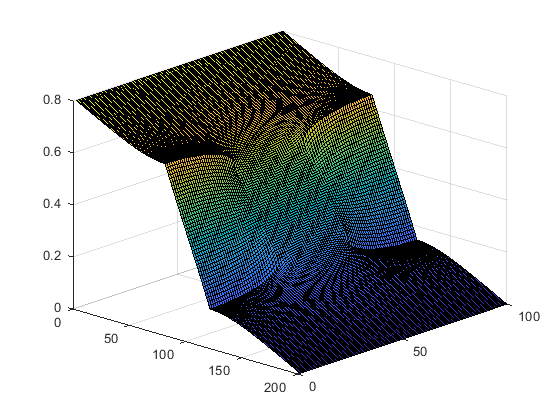

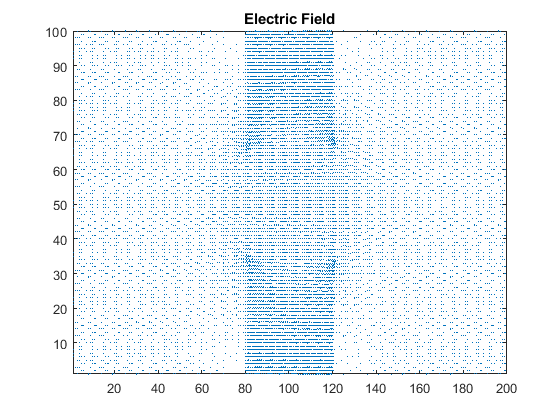

% clear all
clearvars
clearvars -GLOBAL
clc
%close all
format shorte

set(0, 'DefaultFigureWindowStyle', 'docked')
global C

%Physics Constants
C.q_0 = 1.60217653e-19;             % electron charge
C.hb = 1.054571596e-34;             % Dirac constant
C.h = C.hb * 2 * pi;                    % Planck constant
C.m_0 = 9.10938215e-31;             % electron mass
C.kb = 1.3806504e-23;               % Boltzmann constant
C.eps_0 = 8.854187817e-12;          % vacuum permittivity
C.mu_0 = 1.2566370614e-6;           % vacuum permeability
C.c = 299792458;                    % speed of light
C.g = 9.80665; %metres (32.1740 ft) per s²
C.am = 1.66053892e-27;


%Time interval and simulation time 
dt = 0.01e-12;
nt = 500;
%Number of particles - can be run with multiple
np = 10000;
maxXBound = 200e-9;
maxYBound = 100e-9;

%Create the bottleneck - top
bbox_x = [80e-9 120e-9];
bbox_y = [60e-9 100e-9];
%Bottom (uses same X coordinates)
bbox_y2 = [0 40e-9];

%Diffusive option - enable to switch from specular barriers to diffusive
diffusive = 0;

%Initialize positions 
x = rand(np,1)*maxXBound;
y = rand(np,1)*maxYBound;

%For all particles in the region, re-initialize position 
viols = (x(:,1) > bbox_x(1)) & (x(:,1) < bbox_x(2)) & (y(:,1) > bbox_y(1)) & (y(:,1) < bbox_y(2));
while(sum(viols) > 0)
    x(viols) = rand(sum(viols),1)*maxXBound;
    y(viols) = rand(sum(viols),1)*maxYBound;
    
    viols = (x(:,1) > bbox_x(1)) & (x(:,1) < bbox_x(2)) & (y(:,1) > bbox_y(1)) & (y(:,1) < bbox_y(2));
end

%Do the same for the second box
viols = (x(:,1) > bbox_x(1)) & (x(:,1) < bbox_x(2)) & (y(:,1) > bbox_y2(1)) & (y(:,1) < bbox_y2(2));
while(sum(viols) > 0)
    x(viols) = rand(sum(viols),1)*maxXBound;
    y(viols) = rand(sum(viols),1)*maxYBound;
    
    viols = (x(:,1) > bbox_x(1)) & (x(:,1) < bbox_x(2)) & (y(:,1) > bbox_y2(1)) & (y(:,1) < bbox_y2(2));
end

T = 300;
m = 0.26*C.m_0;
Voltage = 0.8;

%New stuff for assignment #3
%Obtain E fields and find acceleration in each direction
[Ex Ey] = EFieldFinder(Voltage,0.33);

We can then use this E field as the input into our Monte Carlo simulation to generate a more accurate scenario of the Electric field in and around the barrier. Below shows a simulation run with this effect. Due to the field directing the electrons from left to right, you can see a high density of electrons bouncing off the barrier on the left side.

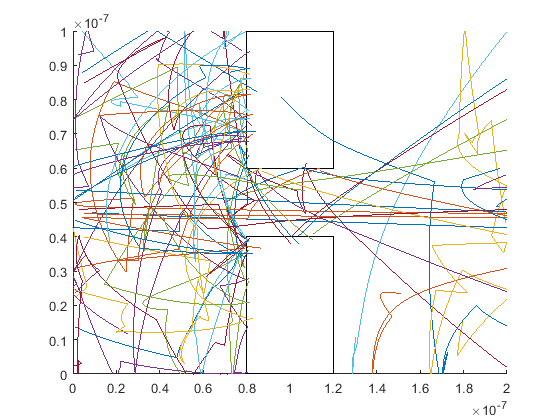

E_force_x = (1e9)*Ex' * C.q_0;
E_force_y = (1e9)*Ey' * C.q_0;
E_accel_x = E_force_x ./ m;
E_accel_y = E_force_y ./ m;

%Velociies
v_th = sqrt(2*C.kb*T/m);
vx = randn(np, 1)*v_th/sqrt(2);
vy = randn(np, 1)*v_th/sqrt(2);

t = 0;
mtc = 0.2e-12;               %Mean time between collisions
P_scat = 1 - exp(-dt/mtc); % scattering probability
T_scat = zeros(1,np);       %Time before scattering
Scatter_Time_Array = 0;
    
%Visualize a certain number of the electroncs
visuals = 7;
watcher = randi(np,visuals);
figure 
for i=2:nt
    %Advance the electron in time updating its position and velocity
    t(i) = t(i-1)+dt;
    T_scat = T_scat + dt; %Increment Time before scattering
    x(:,i) = x(:,i-1) + vx(:,1)*dt;
    y(:,i) = y(:,i-1) + vy(:,1)*dt;
    
    [x_bin, edge_x] = discretize(x(:,i),200);
    [y_bin, edge_y] = discretize(y(:,i),100);
    
    %APPLY ACCELERATION DUE TO E FIELD
    vx(:,1) = vx(:,1) + (1/2)*E_accel_x(sub2ind(size(E_accel_x),x_bin,y_bin))*dt;
    vy(:,1) = vy(:,1) + (1/2)*E_accel_y(sub2ind(size(E_accel_y),x_bin,y_bin))*dt;
    
    hold on;
    for j=1:visuals
        %Create line segments to plot      
        plot([x(watcher(j),i-1) x(watcher(j),i)],[y(watcher(j),i-1) y(watcher(j),i)])
        hold on
    end
    xlim([0 maxXBound])
    ylim([0 maxYBound])

    %Scattering --------------------------------------------------
    scatter = P_scat > rand(np,1);
    
    vx(scatter) = randn(length(vx(scatter)), 1)*v_th/sqrt(2);
    vy(scatter) = randn(length(vy(scatter)), 1)*v_th/sqrt(2);
    %After scattering, average temperature fluctuates but remains averaged
    %around 300K.
    
    %Now affect the Time before scattering:
    Scatter_Time_Array = [Scatter_Time_Array T_scat(scatter)];
    T_scat(scatter) = 0;
    avgScatter = mean(Scatter_Time_Array);
        
  %Reflections for y axis and transmissions for the x asis
  vy((y(:,i)>maxYBound)) = -vy((y(:,i)>maxYBound));
  vy((y(:,i)<0)) = -vy((y(:,i)<0));

  x(x>maxXBound) = x(x>maxXBound)-maxXBound;
  x(x<0) = x(x<0)+maxXBound;
    
  
  %Draw the bottleneck
  if i == 2
      x1 = bbox_x(1);
      x2 = bbox_x(2);
      y1 = bbox_y(1);
      y2 = bbox_y(2);
      boxX = [x1, x1, x2, x2, x1];
        boxY = [y1, y2, y2, y1, y1];
        fill(boxX, boxY, 'w');
        
      x1 = bbox_x(1);
      x2 = bbox_x(2);
      y1 = bbox_y2(1);
      y2 = bbox_y2(2);
      boxX = [x1, x1, x2, x2, x1];
        boxY = [y1, y2, y2, y1, y1];
        fill(boxX, boxY, 'w');  
  end
  
  %Reflections for bottlenecks - shift the particle to avoid getting them
  %stuck!
   
   %Top left edge
   viol_y = (y(:,i) > bbox_y(1));
   viol_x = ((x(:, i-1) < bbox_x(1)) & (x(:, i-1) > 0) & (x(:,i) > bbox_x(1)) & (x(:,i) < maxXBound));
   if (diffusive)
       vx(viol_y & viol_x) = randn(sum(viol_y & viol_x), 1)*v_th/sqrt(2);
   else
       vx(viol_y & viol_x) = -vx(viol_x & viol_y);
       %Shift
       x((viol_y & viol_x), i) = (x((viol_y & viol_x), i-1));
   end
   
   %Top right edge 
   viol_x = ((x(:, i-1) > bbox_x(2)) & (x(:,i) < bbox_x(2)) & (x(:,i) > 0.5*maxXBound) & (x(:, i-1) < maxXBound));
   if (diffusive)
       vx(viol_y & viol_x) = randn(sum(viol_y & viol_x), 1)*v_th/sqrt(2);
   else
     vx(viol_y & viol_x) = -vx(viol_x & viol_y);
     x((viol_y & viol_x), i) = (x((viol_y & viol_x), i-1));
   end
   
   %Horizontal bottleneck - top edge
   viol_y = y(:,i-1) < bbox_y(1) & (y(:,i) > bbox_y(1));
   viol_x = (x(:, i) > bbox_x(1)) & (x(:,i) < bbox_x(2));
   if (diffusive)
       vy(viol_y & viol_x) = randn(sum(viol_y & viol_x), 1)*v_th/sqrt(2);
   else
     vy(viol_y & viol_x) = -vy(viol_x & viol_y);
     y((viol_y & viol_x), i) = (y((viol_y & viol_x), i-1));
   end
   
   %Bottom left edge
   viol_y = (y(:,i) < bbox_y2(2));
   viol_x = ((x(:, i-1) < bbox_x(1)) & (x(:, i-1) > 0) & (x(:,i) > bbox_x(1)) & (x(:,i) < maxXBound));
   if (diffusive)
       vx(viol_y & viol_x) = randn(sum(viol_y & viol_x), 1)*v_th/sqrt(2);
   else
     vx(viol_y & viol_x) = -vx(viol_x & viol_y);
     x((viol_y & viol_x), i) = (x((viol_y & viol_x), i-1));
   end
   
   %Bottom right edge 
   viol_x = ((x(:, i-1) > bbox_x(2)) & (x(:,i) < bbox_x(2)) & (x(:,i) > 0.5*maxXBound)  & (x(:, i-1) < maxXBound));
   if (diffusive)
       vx(viol_y & viol_x) = randn(sum(viol_y & viol_x), 1)*v_th/sqrt(2);
   else
     vx(viol_y & viol_x) = -vx(viol_x & viol_y);
      x((viol_y & viol_x), i) = (x((viol_y & viol_x), i-1));
   end
   
   %Horizontal bottleneck - bottom edge
   viol_y = y(:,i-1) > bbox_y2(2) & (y(:,i) < bbox_y2(2));
   viol_x = (x(:, i) > bbox_x(1)) & (x(:,i) < bbox_x(2));
   if (diffusive)
       vy(viol_y & viol_x) = randn(sum(viol_y & viol_x), 1)*v_th/sqrt(2);
   else
      vy(viol_y & viol_x) = -vy(viol_x & viol_y);
      y((viol_y & viol_x), i) = (y((viol_y & viol_x), i-1));
   end
   
  %pause(0.01);
  
end

# Part 3

As mentioned above in the end of section 2, the field accelerates the particles from left to right, but the barrier stops much of their advancement, reflecting the particles and causing a high density of particles to collect on the left side of the barrier. This is amplified by the simulation functioning as infinite length, meaning the particles that do manage to squeeze through the barrier emerge from the right side back on the left, likely to reflect off the barrier again. 

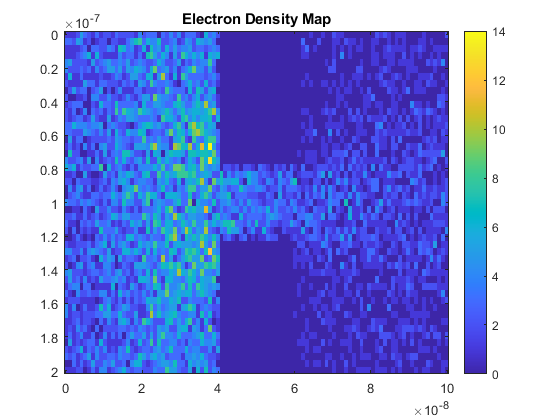

figure
    %Electron Density map
    ptsX = linspace(0, 200e-9, 100);
    ptsY = linspace(0, 100e-9, 50);
    N = histcounts2(y(:,i), x(:,i), ptsY, ptsX);
    imagesc(ptsY,ptsX,N),colorbar,title('Electron Density Map');

The average current through the region can be calculated using the finite difference method with the gradient of the voltage field multiplied by the conductance map. By incrementally increasing the width of the opening in the barrier, we can see the current scale with the opening with - as overall conductance rises, current will as well. 

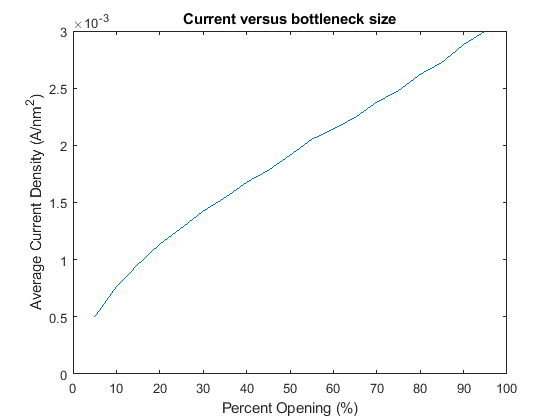

    % Jay Maini 101037537
%clear all
%close all
set(0, 'DefaultFigureWindowStyle', 'docked')

po = linspace(0.05, 0.95, 19);
figure
for i=1:length(po)
    Cur(i) = CurrentFinder(0.8,po(i));
end
plot(po*100, Cur)
hold on
xlabel('Percent Opening (%)')
ylabel('Average Current Density (A/nm^2)')
title('Current versus bottleneck size')

function J_avg = CurrentFinder(v0, percent_open)
    set(0, 'DefaultFigureWindowStyle','docked')

    %v0 = 1;
    %unequal array size
    nx = 200;
    ny = 100;
    V = zeros(nx,ny);
    G = sparse(nx*ny, nx*ny);
    F = zeros(nx*ny,1);

    %Easy adjustment for bottleneck size - useful for function
    %percent_open = 0.33;
    percent_boundary = (1 - percent_open)/2;
    b_height_1 = round(percent_boundary*ny);
    b_height_2 = round(ny-percent_boundary*ny);

    %Make conductivity array 
    cMap = zeros(nx,ny) + 1;
    %Create bottleneck areas
    BNx = [(2/5)*nx (3/5)*nx];
    %BNx = [b_height_1 b_height_2];
    BNy1 = [1 b_height_1];
    BNy2 = [b_height_2 ny];
    %Modify cMap values

    for o = BNx(1):BNx(2)
        for p = BNy1(1):BNy1(2)
            cMap(o,p) = 1e-2;
        end
        for u = BNy2(1):BNy2(2)
            cMap(o,u) = 1e-2;
        end
    end
    
    for i = 1:nx
        for j = 1:ny
            m = j+(i-1)*ny;
            %Edge cases (BC's nodes)
            if (i == 1)
                F(m) = v0;
                G(m,m) = 1;
            elseif (i == nx)
                F(m) = 0;
                G(m,m) = 1;
            elseif (j == 1)
                %Bottom side - only three resistors
                npy = j+1 + (i-1)*ny;
                npx = j + (i-1+1)*ny;
                nmx = j + (i-1-1)*ny;
                nmy = j-1 + (i-1)*ny;

                %Calculate resistances based on conductivity map
                rpx = (cMap(i,j) + cMap(i+1,j))/2;
                rmx = (cMap(i,j) + cMap(i-1,j))/2;
                rpy = (cMap(i,j) + cMap(i,j+1))/2;

                G(m,m) = -(rpx+rmx+rpy);
                G(m,npx) = rpx; 
                G(m,nmx) = rmx;
                G(m,npy) = rpy;
            elseif (j == ny)
                %top side - only three resistors
                nmy = j-1 + (i-1)*ny;
                npx = j + (i-1+1)*ny;
                nmx = j + (i-1-1)*ny;

                %Calculate resistances based on conductivity map
                rpx = (cMap(i,j) + cMap(i+1,j))/2;
                rmx = (cMap(i,j) + cMap(i-1,j))/2;
                rmy = (cMap(i,j) + cMap(i,j-1))/2;

                G(m,m) = -(rpx+rmx+rmy);
                G(m,npx) = rpx; 
                G(m,nmx) = rmx;
                G(m,nmy) = rmy;
            else
                %Inner region - four resistors
                %Define next/previous on the x and y axes
                npy = j+1 + (i-1)*ny;
                nmy = j-1 + (i-1)*ny;
                npx = j + (i-1+1)*ny;
                nmx = j + (i-1-1)*ny;

                %Calculate resistances based on conductivity map
                rpx = (cMap(i,j) + cMap(i+1,j))/2;
                rmx = (cMap(i,j) + cMap(i-1,j))/2;
                rpy = (cMap(i,j) + cMap(i,j+1))/2;
                rmy = (cMap(i,j) + cMap(i,j-1))/2;

                G(m,m) = -(rpx+rmx+rpy+rmy);
                G(m,npx) = rpx; 
                G(m,nmx) = rmx;
                G(m,npy) = rpy;
                G(m,nmy) = rmy;
            end
        end
    end

    %LU Decompsition
    Varr = G\F;
    Varr_temp = reshape(Varr,ny,nx);

    %Output the current obtained
    J = cMap' .*gradient(-Varr_temp);
    %Peak current 
    %J_max = max(J, [], 'all')
    J_avg = mean(J(1,:), 'all');
end

There are a number of ways to increase the acccuracy of the simulation. The most notable would be to increase the resolution of the simulation - currently only running in a 200x100 nanometre region. Higher resolutions would allow for a more informative electric field model, notably at the barrier and at the boundaries specifically. This will, of course, substantially increase the simulation time.